%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CODE CHALLENGE 7 - Template Script
%
% The purpose of this challenge is to estimate the velocity and kenitic
% energy profile of a falling object. 
%
% To complete the challenge, execute the following steps:
% 1) Set an initial condition velocity
% 2) Set values for constants
% 3) Propagate freefall w/ drag for 20 seconds
% 4) Plot the velocity vs. time
% 5) Calculate the change kinetic energy vs. time
% 6) Plot the change in kinetic energy vs. time
%
% NOTE: DO NOT change any variable names already present in the code.
% 
% Upload your team's script to Gradescope when complete.
% 
% NAME YOUR FILE AS Challenge7_Sec{section number}_Group{group breakout #}.m 
% ***Section numbers are 1 or 2*** 
% EX File Name: Challenge7_Sec1_Group15.m 
%
% STUDENT TEAMMATES
% 1) Nina Dolatshahi
% 2) Bill Black
% 3) Drew Miller
% 4) Andrew Logue
% 5) Tristan Workman
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Housekeeping

clear variables; close all; clc;

## Set up

m = .3; % [kg]
g = 9.81; % [m/s^2]
rho = 1.225; % [kg/m^3]
Cd = 1.2; % coefficient of drag
A = 0.0046; % [m^2]
v0 = 0; % [m/s]
ti = 0;
tf = 20;
interval = [ti:tf];

## Propagate with ode45

% free fall with drag for 20 seconds
[t,v] = ode45(@(t,v) accel(t,v,m,g,rho,Cd,A), [ti:tf], v0);

## Plot Velocity vs. Time

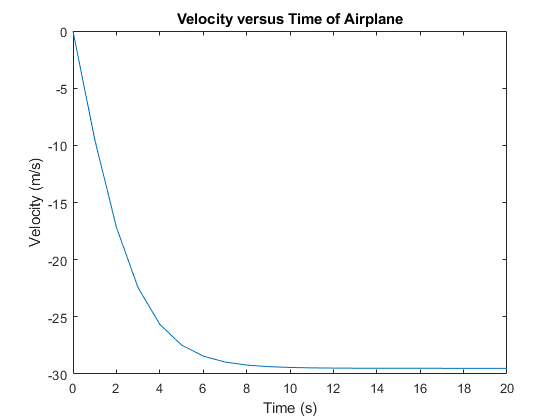

plot(t,v)
title("Velocity versus Time of Airplane")
xlabel("Time (s)")
ylabel("Velocity (m/s)")

## Calculate Kinetic Energy

kinE = 0.5 * m * v.^2; % kinetic energy

## Plot Kinetic Energy vs. Time

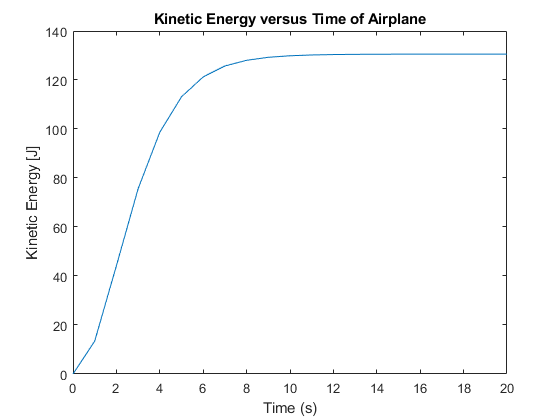

plot(t,kinE)
title("Kinetic Energy versus Time of Airplane")
xlabel("Time (s)")
ylabel("Kinetic Energy [J]")

function dv = accel(t,v,m,g,rho,Cd,A)
dv = (((Cd * .5*(rho * v^2) * A)/m)-g);
end